Step 1 นำเข้ารูป

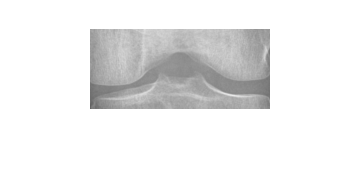

clc;
clear all;
close all;
I1 = imread('train\train\Normal\9099961L.png');

targetSize = [80 180];
r = centerCropWindow2d(size(I1),targetSize);
I2 = imcrop(I1,r);
figure, imshow(I2);

test 1 ทำให้ภาพชัดขึ้น

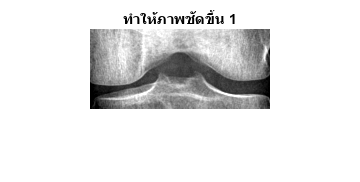

adj1 = imadjust(I2);
figure(2);
imshow(adj1);
title('ทำให้ภาพชัดขึ้น 1');

Step 2

 2. ทำ medfilt2

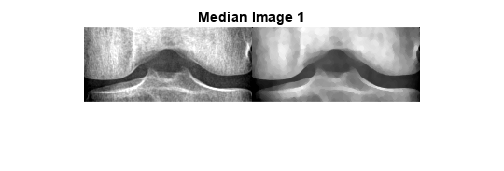

K1 = medfilt2(adj1);
for i = 1:10
K1 = medfilt2(K1);
end
imshowpair(adj1,K1,'montage');
title('Median Image 1');

Step 3

 3. ทำการเปลี่ยนเป็นขาวดำ

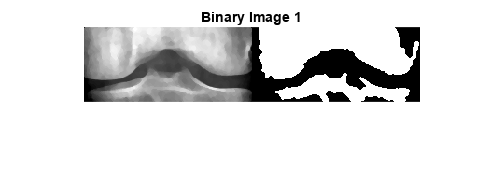

%BW = imbinarize(E)
%BW = im2bw(I,mape,0.4);
level = graythresh(K1);
BW = imbinarize(K1,level);
BWr = imshowpair(K1,BW,'montage');
title('Binary Image 1');

 Step 4

4. ทำการครอปเส้นดำ

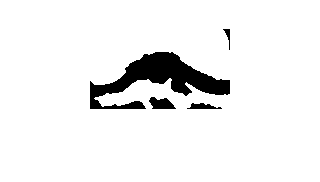

targetSize = [80 140];
r = centerCropWindow2d(size(BW),targetSize);
I2 = imcrop(BW,r);
figure, imshow(I2);

Step 5

5.medfilt อีกรอบ

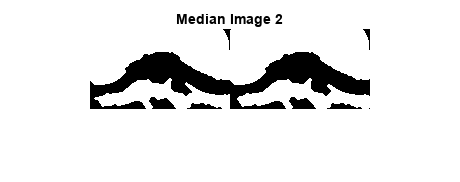

K2 = medfilt2(I2);
for i = 1:10
K2 = medfilt2(K2);
end
imshowpair(I2,K2,'montage');
title('Median Image 2');

Step 6

6.เก็บค่าสี

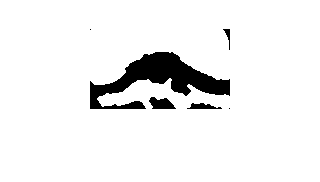

II = imshow(K2);

Step 7

7.ทำค่าเฉลี่ย

Step 8

8.output file

%saveas(gcf,'testtt.png')
II=dir('test\test\Normal\*') % or adsd your folder

II = 571×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for k=1:numel(II)
  name=II(k).name;
  h=hgload(name);
  saveas(h,new_name);
close
end

Error using load
Unable to find file or directory '..fig'.

Error in matlab.graphics.internal.figfile.FigFile/read (line 31)
hgDataVars = load(filename, '-mat', '-regexp', '^hg[M]');

Error in matlab.graphics.internal.figfile.FigFile

Error in hgload (